## **CBM-Toolbox Script for Reversal Learning Data**

This script fits reinforcement learning models to choice data from reversal learning using the Computational Behavioral Modeling toolbox by [Piray et al., 2019](https://journals.plos.org/ploscompbiol/article?id=10.1371/journal.pcbi.1007043)  that applies hierarchical Bayesian inference during concurrent model fitting. In order to run successfully, you need add the cbm-toolbox ('codes') to your matlab-path, and have the 'model_RL' script in the Reversal_Vol_CBM folder. The model script contains a standard Rescorla Wagner model-space with Single Update, individually weighted Double Update and full Double update, with one or two learning rates (win/loss), combined with a softmax (1 beta).    

## **1) Prepare data for cbm**

adapt the paths for your computer

clc 
clear all
close;

system = getenv('COMPUTERNAME');
if strcmp(system, 'C15MW-PS-FO-02') % Teresa's office pc
prefix = 'T:\owncloud\';
addpath(fullfile([prefix, 'cbm-master-original\cbm-master\codes']));
elseif strcmp(system,'C15MN-PS-FO-13') % Teresas laptop
prefix = 'C:\users\katthagt\owncloud\';
addpath(fullfile([prefix, 'cbm-master-original\cbm-master\codes']));
else
prefix = '/Users/larawieland/Owncloud/'; % Lara's PC (without access to Owncloud; just for final upload)
addpath('/Users/larawieland/ownCloud/Shared/Reversal_Vol/scripts_cbm/'); % adapt
addpath('/Users/larawieland/Documents/Promotion/Modeling/cbm/codes/'); % adapt
savepath = '/Users/larawieland/Documents/Promotion/SALAD_3/modeling';
end


cd(fullfile([prefix, '/Shared/Reversal_Vol/scripts_cbm/']));
addpath(fullfile([prefix, '/Shared/Reversal_Vol/scripts_cbm/']));

% addpath('C:\Users\katthagt\ownCloud\Shared\NegSym\Modeling\hgfToolBox_v4.15');
input_path_CT = fullfile([prefix, 'Shared/Reversal_Vol/SALAD_data/HC_Control/']); %behavioral data in mat files
input_path_ST = fullfile([prefix, 'Shared/Reversal_Vol/SALAD_data/HC_Stress/']); 

% load data
input_CT =  dir([input_path_CT, '*WS.mat']);
input_ST =  dir([input_path_ST, '*WS.mat']);
data = {};
nmodels = 6;
nsubjects = length(input_CT); %should have the same number of subjects in both conditions

% subject loop to store all individual choice data in cohensive input file needed for cbm
for sub = 1:length(input_CT)
    data{sub,1}.code   = input_CT(sub).name(7:12);
    data{sub,1}.T      = input_CT(sub).name(14);
        load([input_path_CT input_CT(sub).name], 'R', 'A'); %load individual choice data from Control condition
        fprintf(input_CT(sub).name)
        R_1 = R(~isnan(A));  A_1 = A(~isnan(A)); R_1(R_1==-1)=0; %check whether your model needs losses as 0 or -1
%     Cond_idx_1 = zeros(1,length(R_1)); % initialise Condition index
        clear R A;
        load([input_path_ST input_ST(sub).name], 'R', 'A') %load individual choice data from Stress condition
        fprintf(input_ST(sub).name)
        R_2 = R(~isnan(A));  A_2 = A(~isnan(A)); R_2(R_2==-1)=0; %check whether your model needs losses as 0 or -1
        R = horzcat(R_1,R_2); A = horzcat(A_1,A_2); %append R and A from ST condition to CT condition
%     Cond_idx_2 = ones(1,length(R_2));
%     Cond_idx = horzcat(Cond_idx_1,Cond_idx_2);
    data{sub,1}.trial_idx = length(A_1)+1;
    data{sub,1}.actions = A;
    data{sub,1}.outcome = R;
    clear A A_1 A_2 R R_1 R_2  
end

OPVOL_1A_002_1_150209_1515_WS.mat

OPVOL_1A_002_2_150216_1553_WS.mat

OPVOL_1A_005_1_150323_1611_WS.mat

OPVOL_1A_005_2_150330_1612_WS.mat

OPVOL_1A_009_1_150504_1752_WS.mat

OPVOL_1A_009_2_150511_1747_WS.mat

OPVOL_1A_013_1_151109_1507_WS.mat

OPVOL_1A_013_2_151116_1615_WS.mat

OPVOL_1A_014_1_150615_1649_WS.mat

OPVOL_1A_014_2_150623_1542_WS.mat

OPVOL_1A_018_1_150629_1732_WS.mat

OPVOL_1A_018_2_150706_1747_WS.mat

OPVOL_1A_019_1_150713_1612_WS.mat

OPVOL_1A_019_2_150720_1525_WS.mat

OPVOL_1A_020_1_150713_1753_WS.mat

OPVOL_1A_020_2_150720_1752_WS.mat

OPVOL_1A_027_1_151012_1446_WS.mat

OPVOL_1A_027_2_151105_1619_WS.mat

OPVOL_1A_028_1_151112_1741_WS.mat

OPVOL_1A_028_2_151119_1741_WS.mat

OPVOL_1A_030_1_151012_1632_WS.mat

OPVOL_1A_030_2_151116_1500_WS.mat

OPVOL_1A_039_1_160114_1442_WS.mat

OPVOL_1A_039_2_160128_1444_WS.mat

OPVOL_1A_042_1_160218_1609_WS.mat

OPVOL_1A_042_2_160225_1605_WS.mat

OPVOL_1B_007_2_150223_1714_WS.mat

OPVOL_1B_007_1_150216_1732_WS.mat

OPVOL_1B_008_2_150323_1428_WS.mat

OPVOL_1B_008_1_150316_1418_WS.mat

OPVOL_1B_010_2_150420_1603_WS.mat

OPVOL_1B_010_1_150413_1623_WS.mat

OPVOL_1B_015_2_150703_1507_WS.mat

OPVOL_1B_015_1_150622_1448_WS.mat

OPVOL_1B_016_2_150506_1705_WS.mat

OPVOL_1B_016_1_150427_1550_WS.mat

OPVOL_1B_017_2_150713_1445_WS.mat

OPVOL_1B_017_1_150706_1445_WS.mat

OPVOL_1B_022_2_150727_1615_WS.mat

OPVOL_1B_022_1_150720_1650_WS.mat

OPVOL_1B_023_2_150730_1724_WS.mat

OPVOL_1B_023_1_150723_1802_WS.mat

OPVOL_1B_026_2_151015_1440_WS.mat

OPVOL_1B_026_1_151008_1501_WS.mat

OPVOL_1B_033_2_151123_1611_WS.mat

OPVOL_1B_033_1_151116_1758_WS.mat

OPVOL_1B_034_2_151217_1446_WS.mat

OPVOL_1B_034_1_151210_1501_WS.mat

OPVOL_1B_052_2_160418_1606_WS.mat

OPVOL_1B_052_1_160411_1633_WS.mat

OPVOL_1B_053_2_160407_1731_WS.mat

OPVOL_1B_053_1_160331_1701_WS.mat

OPVOL_1B_056_2_160609_1440_WS.mat

OPVOL_1B_056_1_160602_1447_WS.mat

OPVOL_1B_057_2_160609_1559_WS.mat

OPVOL_1B_057_1_160602_1609_WS.mat

## 2) check if model is running correctly with random parameters (no actual fitting)

Note: The cbm files were modified, so that one learning script can fit different models depending on the model number, that is the third input now in the standard fitting function loglik = model_RL(parameters,subj, model_no). Check section 3 for amount of free parameters for each model.

Model numbers (model_no):

1 --> SU 1 alpha, 2 --> SU 2 alphas

3 --> iDU 1 alpha, 2 --> iDU 2 alphas

4 --> DU 1 alpha, 2 --> DU 2 alphas 

% loglik = model_RL(parameters,subj1)
load hbi_bothCond_scaling_DU.mat
% xlsxparams = NaN(length(data),5); 
% est = struct;

for sub = 1:length(data)
subj = data{sub}; 
parameters = cbm.output.parameters{2,1}; 
% parameters = parameters(sub,:);
[F1,traj] = model_RL_DU2al_2betas_withStress_scaling_onlybetas(parameters,subj),
    
F(sub) = model_RL_DU2al_2betas_withStress_scaling_onlybetas(parameters,subj),
geom_mLME(sub,1) = exp(F(sub)/length(data{sub, 1}.outcome));

fitter(sub, 1) = geom_mLME(sub, 1)>.5;
%parameters = rand(1,3);
%[F1] = model_nolearning_qbias(parameters,subj);
est(sub).traj = traj;
est(sub).loglik = F1;
est(sub).trial_idx = data{sub,1}.trial_idx; 
est(sub).code = data{sub,1}.code; 
% plot(traj.q(1:160,:)); hold on;
% scatter(1:160, abs(traj.a(1:160)-2)); hold on;
% scatter(1:160, traj.o(1:160)+0.05); legend('value 1', 'value 2', 'actions', 'outcomes'); hold off
% sig_params = sgm(parameters(1:3),1);
% betas = parameters(4:5);
% all_params = horzcat(sig_params,betas);
% xlsxparams(sub,:) = all_params;
end

F1 = -218.4336

traj = struct with fields:
     a: [318×1 double]
     o: [319×1 double]
     q: [318×2 double]
    da: [2×318 double]


F = -218.4336

F1 = -217.8216

traj = struct with fields:
     a: [316×1 double]
     o: [317×1 double]
     q: [316×2 double]
    da: [2×316 double]


F =  -218.4336 -217.8216


F1 = -213.0130

traj = struct with fields:
     a: [311×1 double]
     o: [312×1 double]
     q: [311×2 double]
    da: [2×311 double]


F =  -218.4336 -217.8216 -213.0130


F1 = -216.4758

traj = struct with fields:
     a: [319×1 double]
     o: [320×1 double]
     q: [319×2 double]
    da: [2×319 double]


F =  -218.4336 -217.8216 -213.0130 -216.4758


F1 = -220.0183

traj = struct with fields:
     a: [319×1 double]
     o: [320×1 double]
     q: [319×2 double]
    da: [2×319 double]


F =  -218.4336 -217.8216 -213.0130 -216.4758 -220.0183


F1 = -218.7596

traj = struct with fields:
     a: [320×1 double]
     o: [321×1 double]
     q: [320×2 double]
    da: [2×320 double]


F =  -218.4336 -217.8216 -213.0130 -216.4758 -220.0183 -218.7596


F1 = -217.5017

traj = struct with fields:
     a: [319×1 double]
     o: [320×1 double]
     q: [319×2 double]
    da: [2×319 double]


F =  -218.4336 -217.8216 -213.0130 -216.4758 -220.0183 -218.7596 -217.5017


F1 = -218.4183

traj = struct with fields:
     a: [317×1 double]
     o: [318×1 double]
     q: [317×2 double]
    da: [2×317 double]


F =  -218.4336 -217.8216 -213.0130 -216.4758 -220.0183 -218.7596 -217.5017 -218.4183


F1 = -218.7267

traj = struct with fields:
     a: [320×1 double]
     o: [321×1 double]
     q: [320×2 double]
    da: [2×320 double]


F =  -218.4336 -217.8216 -213.0130 -216.4758 -220.0183 -218.7596 -217.5017 -218.4183 -218.7267


F1 = -219.0525

traj = struct with fields:
     a: [317×1 double]
     o: [318×1 double]
     q: [317×2 double]
    da: [2×317 double]


F =  -218.4336 -217.8216 -213.0130 -216.4758 -220.0183 -218.7596 -217.5017 -218.4183 -218.7267 -219.0525


F1 = -218.1107

traj = struct with fields:
     a: [318×1 double]
     o: [319×1 double]
     q: [318×2 double]
    da: [2×318 double]


F =  -218.4336 -217.8216 -213.0130 -216.4758 -220.0183 -218.7596 -217.5017 -218.4183 -218.7267 -219.0525 -218.1107


F1 = -217.0651

traj = struct with fields:
     a: [319×1 double]
     o: [320×1 double]
     q: [319×2 double]
    da: [2×319 double]


F =  -218.4336 -217.8216 -213.0130 -216.4758 -220.0183 -218.7596 -217.5017 -218.4183 -218.7267 -219.0525 -218.1107 -217.0651


F1 = -219.0391

traj = struct with fields:
     a: [320×1 double]
     o: [321×1 double]
     q: [320×2 double]
    da: [2×320 double]


F =  -218.4336 -217.8216 -213.0130 -216.4758 -220.0183 -218.7596 -217.5017 -218.4183 -218.7267 -219.0525 -218.1107 -217.0651 -219.0391


F1 = -216.4549

traj = struct with fields:
     a: [316×1 double]
     o: [317×1 double]
     q: [316×2 double]
    da: [2×316 double]


F =  -218.4336 -217.8216 -213.0130 -216.4758 -220.0183 -218.7596 -217.5017 -218.4183 -218.7267 -219.0525 -218.1107 -217.0651 -219.0391 -216.4549


F1 = -216.8071

traj = struct with fields:
     a: [319×1 double]
     o: [320×1 double]
     q: [319×2 double]
    da: [2×319 double]


F =  -218.4336 -217.8216 -213.0130 -216.4758 -220.0183 -218.7596 -217.5017 -218.4183 -218.7267 -219.0525 -218.1107 -217.0651 -219.0391 -216.4549 -216.8071


F1 = -217.5941

traj = struct with fields:
     a: [318×1 double]
     o: [319×1 double]
     q: [318×2 double]
    da: [2×318 double]


F =  -218.4336 -217.8216 -213.0130 -216.4758 -220.0183 -218.7596 -217.5017 -218.4183 -218.7267 -219.0525 -218.1107 -217.0651 -219.0391 -216.4549 -216.8071 -217.5941


F1 = -216.8448

traj = struct with fields:
     a: [317×1 double]
     o: [318×1 double]
     q: [317×2 double]
    da: [2×317 double]


F =  -218.4336 -217.8216 -213.0130 -216.4758 -220.0183 -218.7596 -217.5017 -218.4183 -218.7267 -219.0525 -218.1107 -217.0651 -219.0391 -216.4549 -216.8071 -217.5941 -216.8448


F1 = -215.8217

traj = struct with fields:
     a: [315×1 double]
     o: [316×1 double]
     q: [315×2 double]
    da: [2×315 double]


F =  -218.4336 -217.8216 -213.0130 -216.4758 -220.0183 -218.7596 -217.5017 -218.4183 -218.7267 -219.0525 -218.1107 -217.0651 -219.0391 -216.4549 -216.8071 -217.5941 -216.8448 -215.8217


F1 = -217.8491

traj = struct with fields:
     a: [318×1 double]
     o: [319×1 double]
     q: [318×2 double]
    da: [2×318 double]


F =  -218.4336 -217.8216 -213.0130 -216.4758 -220.0183 -218.7596 -217.5017 -218.4183 -218.7267 -219.0525 -218.1107 -217.0651 -219.0391 -216.4549 -216.8071 -217.5941 -216.8448 -215.8217 -217.8491


F1 = -212.9621

traj = struct with fields:
     a: [311×1 double]
     o: [312×1 double]
     q: [311×2 double]
    da: [2×311 double]


F =  -218.4336 -217.8216 -213.0130 -216.4758 -220.0183 -218.7596 -217.5017 -218.4183 -218.7267 -219.0525 -218.1107 -217.0651 -219.0391 -216.4549 -216.8071 -217.5941 -216.8448 -215.8217 -217.8491 -212.9621


F1 = -217.4663

traj = struct with fields:
     a: [319×1 double]
     o: [320×1 double]
     q: [319×2 double]
    da: [2×319 double]


F =  -218.4336 -217.8216 -213.0130 -216.4758 -220.0183 -218.7596 -217.5017 -218.4183 -218.7267 -219.0525 -218.1107 -217.0651 -219.0391 -216.4549 -216.8071 -217.5941 -216.8448 -215.8217 -217.8491 -212.9621 -217.4663


F1 = -218.0042

traj = struct with fields:
     a: [319×1 double]
     o: [320×1 double]
     q: [319×2 double]
    da: [2×319 double]


F =  -218.4336 -217.8216 -213.0130 -216.4758 -220.0183 -218.7596 -217.5017 -218.4183 -218.7267 -219.0525 -218.1107 -217.0651 -219.0391 -216.4549 -216.8071 -217.5941 -216.8448 -215.8217 -217.8491 -212.9621 -217.4663 -218.0042


F1 = -220.2702

traj = struct with fields:
     a: [320×1 double]
     o: [321×1 double]
     q: [320×2 double]
    da: [2×320 double]


F =  -218.4336 -217.8216 -213.0130 -216.4758 -220.0183 -218.7596 -217.5017 -218.4183 -218.7267 -219.0525 -218.1107 -217.0651 -219.0391 -216.4549 -216.8071 -217.5941 -216.8448 -215.8217 -217.8491 -212.9621 -217.4663 -218.0042 -220.2702


F1 = -217.2996

traj = struct with fields:
     a: [320×1 double]
     o: [321×1 double]
     q: [320×2 double]
    da: [2×320 double]


F =  -218.4336 -217.8216 -213.0130 -216.4758 -220.0183 -218.7596 -217.5017 -218.4183 -218.7267 -219.0525 -218.1107 -217.0651 -219.0391 -216.4549 -216.8071 -217.5941 -216.8448 -215.8217 -217.8491 -212.9621 -217.4663 -218.0042 -220.2702 -217.2996


F1 = -215.0671

traj = struct with fields:
     a: [315×1 double]
     o: [316×1 double]
     q: [315×2 double]
    da: [2×315 double]


F =  -218.4336 -217.8216 -213.0130 -216.4758 -220.0183 -218.7596 -217.5017 -218.4183 -218.7267 -219.0525 -218.1107 -217.0651 -219.0391 -216.4549 -216.8071 -217.5941 -216.8448 -215.8217 -217.8491 -212.9621 -217.4663 -218.0042 -220.2702 -217.2996 -215.0671


F1 = -218.1690

traj = struct with fields:
     a: [319×1 double]
     o: [320×1 double]
     q: [319×2 double]
    da: [2×319 double]


F =  -218.4336 -217.8216 -213.0130 -216.4758 -220.0183 -218.7596 -217.5017 -218.4183 -218.7267 -219.0525 -218.1107 -217.0651 -219.0391 -216.4549 -216.8071 -217.5941 -216.8448 -215.8217 -217.8491 -212.9621 -217.4663 -218.0042 -220.2702 -217.2996 -215.0671 -218.1690


F1 = -217.7933

traj = struct with fields:
     a: [319×1 double]
     o: [320×1 double]
     q: [319×2 double]
    da: [2×319 double]


F =  -218.4336 -217.8216 -213.0130 -216.4758 -220.0183 -218.7596 -217.5017 -218.4183 -218.7267 -219.0525 -218.1107 -217.0651 -219.0391 -216.4549 -216.8071 -217.5941 -216.8448 -215.8217 -217.8491 -212.9621 -217.4663 -218.0042 -220.2702 -217.2996 -215.0671 -218.1690 -217.7933


F1 = -215.2694

traj = struct with fields:
     a: [315×1 double]
     o: [316×1 double]
     q: [315×2 double]
    da: [2×315 double]


F =  -218.4336 -217.8216 -213.0130 -216.4758 -220.0183 -218.7596 -217.5017 -218.4183 -218.7267 -219.0525 -218.1107 -217.0651 -219.0391 -216.4549 -216.8071 -217.5941 -216.8448 -215.8217 -217.8491 -212.9621 -217.4663 -218.0042 -220.2702 -217.2996 -215.0671 -218.1690 -217.7933 -215.2694


save bestModel_DU2al2betas_scaling_N28_both_cond est

## 3) use cbm for initial model fitting and group prior estimation 

The function 'cbm_lap' fits every model to each subject data separately (i.e. in a non-hierarchical fashion, so that only (random) individuals are fitted first without any (fixed) group information)

It uses Laplace approximation needing a normal prior for every parameter ([see manual](file:///C:/Users/katthagt/ownCloud/cbm-master/manual.html)) with: 

mean = 0 and variance = 6.25. 

All parameters are normalized (-Inf to Inf), thus parameters between 0:1 need to be sigmoid-transformed (--> logit-space) and parameters > 0 must be exponential-transformed (log-space) in the beginning of the learning model-file.

crucial function: cbm_lap(data, @model, priors, output file,[ ], model_no)

v                = 6.25;    % variance is the same for all priors
% name output files
fname_RL = {};
% fname_RL{1}='SU1al_CT.mat';  fname_RL{2}='SU2al_CT.mat'; fname_RL{3}='iDU1al_CT.mat'; 
% fname_RL{4}='iDU2al_bothcond_adding.mat'; fname_RL{5}='DU1al_CT.mat'; fname_RL{6}='DU2al_CT.mat'; 
  fname_RL{1}='DU2al_bothcond_NoScaling.mat';
  fname_RL{2}='DU2al_bothcond_scaling_onlybetas.mat';
  fname_RL{3}='DU2al_bothcond_scaling_onlylearning.mat';
  fname_RL{4}='DU2al_bothcond_scaling_allparams.mat';


% set amount of priors for each model
% prior(1)     = struct('mean', zeros(5,1),'variance',v);          % 2 free parameters (alpha, beta)
% prior(2)     = struct('mean', zeros(7,1),'variance',v);          % 3 free parameters (alpha_rew, alpha_pun, beta) 
% prior(3)     = struct('mean', zeros(8,1),'variance',v);          % 3 free parameters (alpha, kappa, beta)
% prior(4)     = struct('mean', zeros(10,1),'variance',v);          % 4 free parameters (alpha_rew, alpha_pun, kappa, beta) 

prior(1)     = struct('mean', zeros(4,1),'variance',v);          % 2 free parameters (alpha, beta)
prior(2)     = struct('mean', zeros(6,1),'variance',v);          % 2 free parameters (alpha, beta) 
prior(3)     = struct('mean', zeros(6,1),'variance',v);          % 3 free parameters (alpha, kappa, beta)
prior(4)     = struct('mean', zeros(8,1),'variance',v);          % 3 free parameters (alpha, kappa, beta) 

cbm_lap(data, @model_RL_DU2al_2betas_withStress_NoScaling,            prior(1), char(fname_RL(1))); % last input for model number!
cbm_lap(data, @model_RL_DU2al_2betas_withStress_scaling_onlybetas,    prior(2), char(fname_RL(2))); % last input for model number!
cbm_lap(data, @model_RL_DU2al_2betas_withStress_scaling_onlylearning, prior(3), char(fname_RL(3))); % last input for model number!
cbm_lap(data, @model_RL_DU2al_2betas_withStress_scaling_allparams,    prior(4), char(fname_RL(4)));% last input for model number!
% cbm_lap(data, @model_RL_DU1al,  prior(5), char(fname_RL(5))); % last input for model number!
% cbm_lap(data, @model_RL_DU2al,  prior(6), char(fname_RL(6))); % last input for model number!

## **Read out parameters for simultanuous fitting of control and stress condition**

clear all
% load iDU2al_bothcond_scaling.mat
load hbi_bothCond_scaling_full.mat

% read out parameters of free learning parameters (not the best model!)
params     = cbm.output.parameters{2};
p_neutral  = params(:, 1:5);


% control condition parameters
al_neutral = sgm(p_neutral(:,1:2), 1); % loss, reward
ka_neutral = sgm(p_neutral(:,3), 1);
be         = exp(p_neutral(:,4:end)); % reward, loss

if length(params) > 5
p_stress   = params(:, 6:end);

% scaling factors for stress
scale_al_stress  = p_stress(:,1:2); 
scale_ka_stress  = p_stress(:,3); 

% full parameters for stress
al_stress(:,1) = sgm((al_neutral(:,1)+scale_al_stress(:,1)),1);
al_stress(:,2) = sgm((al_neutral(:,2)+scale_al_stress(:,2)),1);
ka_stress(:,1) = sgm((ka_neutral+scale_ka_stress),1);
end


## 5) hierarchical Bayesian inference: concurrent model fitting

Here, we use the parameters from step 3 as priors for concurrent model-fitting (all models are fitted within one step). Using hierarchical bayesian inference, random (individuals') parameters inform the fixed (group) parameters according to the likelihood of this model being the best model for the respective subject ("responsibility"). 

Central function: cbm_hbi(data,nmodels,fcbm_maps,fname_hbi);

% 2nd input: a cell input containing function handle to models (== @ before the name of the function)
models = {@model_RL_DU2al_2betas_withStress_NoScaling, @model_RL_DU2al_2betas_withStress_scaling_onlybetas, @model_RL_DU2al_2betas_withStress_scaling_onlylearning,@model_RL_DU2al_2betas_withStress_scaling_allparams};
% 3rd input: another cell input containing file-address to files saved by
% cbm_lap, note that they corresponds to models (so pay attention to the order)
fcbm_maps = {'DU2al_bothcond_NoScaling.mat',            'DU2al_bothcond_scaling_onlybetas.mat', ...
             'DU2al_bothcond_scaling_onlylearning.mat', 'DU2al_bothcond_scaling_allparams.mat'};
% 4th input: a file address for saving the output
fname_hbi = 'hbi_bothCond_scaling_DU.mat';

cbm_hbi(data,models,fcbm_maps,fname_hbi);

Error using load
Unable to read file 'DU2al_bothcond_scaling_onlybetas.mat'. No such file or directory.

Error in cbm_hbi_init (line 24)
        fcbm_map  = load(fcbm_map); cbm_maps{k} = fcbm_map.cbm;

Error in cbm_hbi (line 61)
[inits,priors]= cbm_hbi_init(fcbm_maps,hyper,isnull,

cbm_hbi_null(data,fname_hbi);

## 6) Plot the hbi parameters

As in step 4, display the fitted parameters as implemented in the toolbox function: 'cbm_hbi_plot(fname_hbi, model_names, param_names, transform, model of interest)'

1st input is the file-address of the file saved by cbm_hbi

2nd input: a cell input containing model names

3rd input: another cell input containing parameter names of the winning model 

4th input: another cell input containing transformation function associated with each parameter of the winning model

5th input: optional, indicates model of interest

fname_hbi = 'hbi_bothCond_scaling_DU.mat'; % 1st input is the file-address of the file saved by cbm_hbi
hbi = load('hbi_bothCond_scaling_DU.mat');
cbm = hbi.cbm;
cbm.output 

ans = struct with fields:
                     parameters: {4×1 cell}
                 responsibility: [28×4 double]
                     group_mean: {[0.0272 0.1795 0.9679 0.1007]  [-1.6648 -0.9051 1.9348 1.5282 -0.0075 -0.1061]  [0.5763 -2.5121 1.4251 0.5263 -1.8097 0.2379]  [1.5689e-06 1.5689e-06 6.3735e-06 6.7979e-07 1.7578e-06 1.7578e-06 1.3169e-05 -1.2705e-06]}
    group_hierarchical_errorbar: {[0.0844 0.0971 0.1599 0.1170]  [0.2159 0.1905 0.1691 0.1567 0.0839 0.1648]  [0.2170 0.5961 0.3405 0.2952 0.6408 0.9559]  [0.1414 0.1414 0.1414 0.1414 0.1414 0.1414 0.1414 0.1414]}
                model_frequency: [0.2966 0.5543 0.1492 3.8733e-06]
                exceedance_prob: [0.0723 0.9237 0.0039 3.0000e-06]
      protected_exceedance_prob: [0.0723 0.9239 0.0039 2.0000e-06]



[M,I]=max(cbm.output.exceedance_prob);   % find the model with the highest exceedance probability index I

param_names(1).p        = {'alpha win', 'alpha loss','beta win', 'beta loss'};
param_names(1).transform= {'sigmoid', 'sigmoid', 'exp', 'exp'};
param_names(2).p        = {'alpha CT win', 'alpha CT loss', 'beta CT win', 'beta CT loss', 'alpha ST win', 'alpha ST loss'};
param_names(2).transform= {'sigmoid', 'sigmoid', 'exp', 'exp', 'sigmoid', 'sigmoid'};
param_names(3).p        = {'alpha win', 'alpha loss','beta win CT', 'beta loss CT', 'beta win ST', 'beta loss ST'};
param_names(3).transform= {'sigmoid', 'sigmoid', 'exp', 'exp', 'exp', 'exp'};
param_names(4).p        = {'alpha CT win', 'alpha CT loss', 'alpha ST win', 'alpha ST loss', 'beta CT win', 'beta CT loss', 'beta ST win', 'beta ST loss'};
param_names(4).transform= {'sigmoid','sigmoid','sigmoid','sigmoid','exp','exp','exp','exp'};
% param_names(5)   = param_names(1);
% param_names(6)   = param_names(2);

cbm_hbi_plot(fname_hbi, fname_hbi, param_names(I).p, param_names(I).transform, I) % this function creates a model comparison plot (exceednace probability and model frequency) as well as

Undefined function or variable 'cbm_hbi_plot'.

## 4) Check the fitted parameters

Note that the parameters are normalized before saving, and not to be back-transformed to make sense in the model. 

params contains all fitted parameters (subjects, parameters, model_no):

1st column: alpha_both     2nd alpha_reward     3rd alpha_loss    4th kappa     5th beta 

You can pick between the parameters from the individually fitted models and the ones from hierarchical Bayesian inference with "whichfit" 

params = NaN(nsubjects, 6, nmodels);
whichfit = 2; % for cbm, 2 for hbi
 
if whichfit == 2
     fname_hbi = load('hbi_bothCond_scaling_DU.mat');
     cbm = fname_hbi.cbm;
end

for i = 1:nmodels
if whichfit == 1
    model_name = load(fname_RL{i});
    cbm = model_name.cbm;
    nd_params = cbm.output.parameters;
else
    nd_params = cbm.output.parameters{i};
    params(:,6,i) = cbm.output.responsibility(:,i);
end
        
if mod(i,2)
params(:,1,i)= 1./(1+exp(-nd_params(:,1)));  % alpha
    if (i == 1 | i == 5)
params(:,5,i)= exp(nd_params(:,2));     % beta
    elseif i==3
params(:,4,i)= 1./(1+exp(-nd_params(:,2))); % kappa
params(:,5,i)= exp(nd_params(:,3));        % beta
    end
elseif ~mod(i,2)
params(:,2:3,i)= 1./(1+exp(-nd_params(:,1:2))); % alpha_win, alpha_loss
    if (i == 2 | i == 6)
params(:,5,i)= exp(nd_params(:,3));     % beta
    elseif i==4
params(:,4,i)= 1./(1+exp(-nd_params(:,3))); % kappa
params(:,5,i)= exp(nd_params(:,4));        % beta
    end
end
clear nd_params
end

Index exceeds array bounds.


% % Plot parameters

for i = 1:3     %number of max free parameters
figure; hold on;
if i == 1       % alpha   
for j = 1:nmodels 
    subplot(3,2,j);
    if mod(j,2)
    scatter((1:nsubjects),params(:,1,j));
    else
    scatter((1:nsubjects),params(:,2,j)); hold on;
    scatter((1:nsubjects),params(:,3,j), 'r'); hold off;    
    end
    if j==1
    title('1. SU1alpha: alpha');
    elseif j==2
    title('2. SU2alphas: alpha reward (blue) and alpha loss(red)');
    elseif j==3
    title('3. iDU1alpha: alpha');
    elseif j==4
    title('4. iDU2alphas: alpha reward (blue) and alpha loss(red)');
    elseif j==5
    title('5. DU1alpha: alpha');
    elseif j==6
    title('6. DU2alphas: alpha reward (blue) and alpha loss(red)');
    end
    
end
elseif i ==2 % kappa
for j = 1:nmodels 
    if j==3
    subplot(2,1,1)
    title('3. iDU1alpha: kappa');
    scatter((1:nsubjects),params(:,4,j));
    elseif j==4
    subplot(2,1,2)
    title('4. iDU2alphas: kappa'); 
    scatter((1:nsubjects), params(:,4,j));
    end
end
    
elseif i ==3 % beta
    for j = 1:nmodels   
    subplot(3,2,j);
        scatter((1:nsubjects), params(:,5,j));
        if j==1
        title('1. SU1alpha: beta');
        elseif j==2
        title('2. SU2alphas: beta');
        elseif j==3
        title('3. iDU1alpha: beta');
        elseif j==4
        title('4. iDU2alphas: beta');
        elseif j==5
        title('5. DU1alpha: beta');
        elseif j==6
        title('6. DU2alphas: beta');
        end
    end
end    
    hold off;
end

## 5. Compare group parameters and model comparison

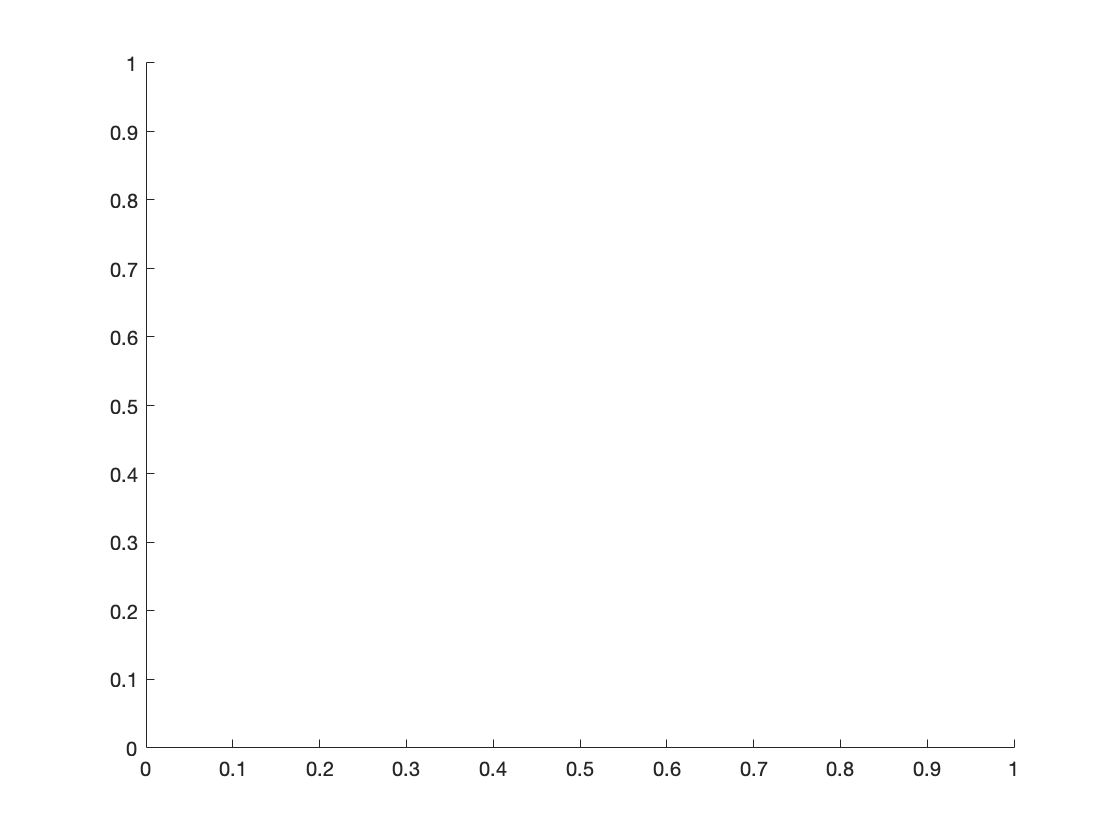

hold off; figure 

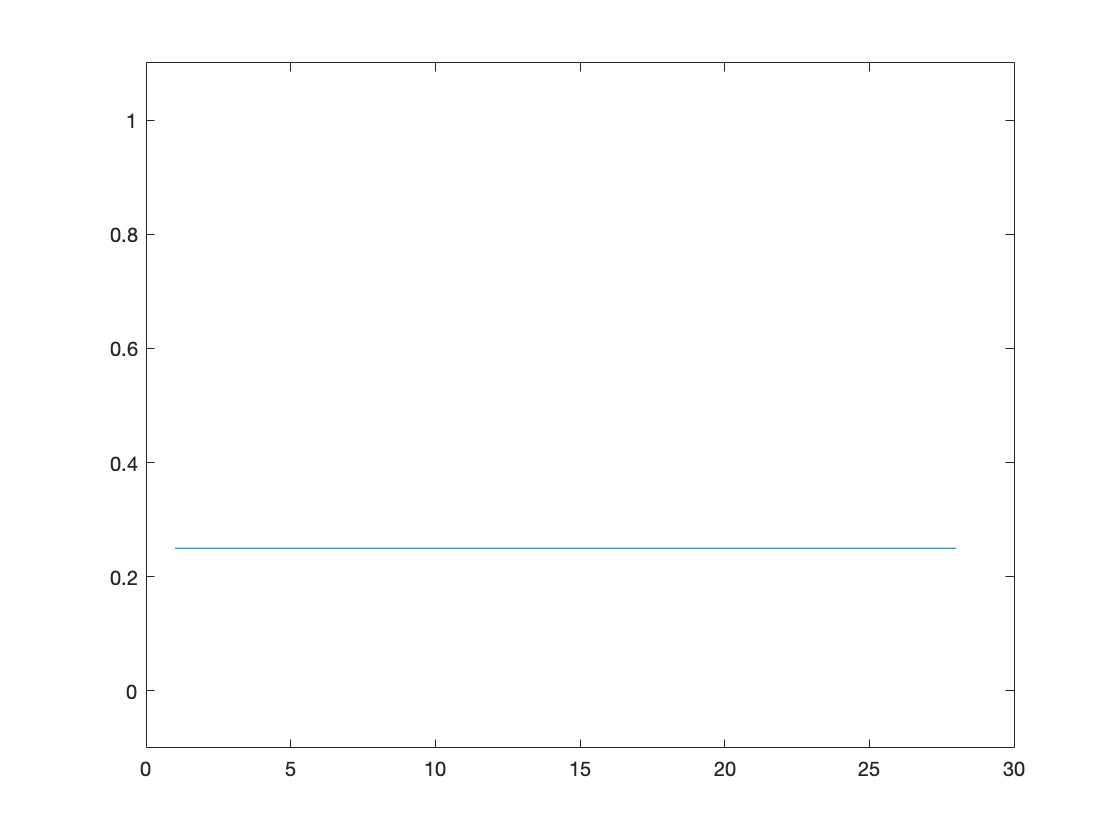

parameters_RL = cbm.output.parameters{1};
%parameters_dualRL = cbm.output.parameters{2};
responsibility = cbm.output.responsibility;
plot(responsibility(:,2)); ylim([-.1 1.1]);


% estimate protected exceedance probabilities (taking into account the null hypothesis that no model in the model space is most likely across the population (i.e. any difference between model frequencies is due to chance).
fname_hbi = 'hbi_bothCond_scaling_DU.mat'; % file-address of the file saved by cbm_hbi
cbm_hbi_null(data,fname_hbi); % updates the upper file now containing  the pxps

Undefined function or variable 'data'.

## **6. Plot scaling parameters for beta win and beta loss**

load('hbi_bothCond_scaling_DU.mat') % file-address of the file saved by cbm_hbi

params = cbm.output.parameters{2}; % write out parameters from winning model 2

alpha_win = params(:,1);
sgm_alpha_win = sgm(alpha_win(:,1),1); % transform alpha back to 0-1

alpha_loss = params(:,2);
sgm_alpha_loss = sgm(alpha_loss(:,1),1); % transform alpha back to 0-1

beta_win = params(:,3);
tr_beta_win = exp(beta_win);

beta_loss = params(:,4);
tr_beta_loss = exp(beta_loss);

scaling_win = params(:,5);
scaling_loss = params(:,6);

tr_stress_beta_win = exp(beta_win+scaling_win);
tr_stress_beta_loss = exp(beta_loss+scaling_loss);
   
for sub = 1:length(data)
subj = data{sub}; 
parameters = cbm.output.parameters{2,1};     
loglik(sub) = model_RL_DU2al_2betas_withStress_scaling_onlybetas(parameters,subj);
geom_mLME(sub,1) = exp(loglik(sub)/length(data{sub, 1}.outcome));
fitter(sub, 1) = geom_mLME(sub, 1)>.5;
end

loglikt = loglik';

% create a table for export and combination with behavioral data

al_win      = NaN(1, length(data));
al_loss     = NaN(1, length(data));
bet_win     = NaN(1, length(data));
bet_loss    = NaN(1, length(data));
sc_win      = NaN(1, length(data));
sc_loss     = NaN(1, length(data));
sc_bet_win  = NaN(1, length(data));
sc_bet_loss = NaN(1, length(data));
modelfit    = NaN(1, length(data));


for sub = 1:length(data)
    
    al_win(:,sub) = sgm_alpha_win(sub,:);
    al_loss(:,sub) = sgm_alpha_loss(sub,:);
    bet_win(:,sub) = tr_beta_win(sub,:);
    bet_loss(:,sub) = tr_beta_loss(sub,:);
    sc_win(:,sub) = scaling_win(sub,:);
    sc_loss(:,sub) = scaling_loss(sub,:);
    sc_bet_win(:,sub) = tr_stress_beta_win(sub,:);
    sc_bet_loss(:,sub) = tr_stress_beta_loss(sub,:);
    modelfit(:,sub) = loglikt(sub,:);
    
%     col_names = {'sub_id'};
%     subname(sub,:) = cell2table({data{sub, 1}.code},'VariableNames',col_names);
%     
    table(1:length(data),:) = [al_win', al_loss', bet_win', bet_loss', sc_win', sc_loss', sc_bet_win', sc_bet_loss', modelfit']
end

table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
    0.2271    0.5711    3.0206    1.7192   -0.1498    0.2855    2.6004    2.2873 -217.8216
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
    0.2271    0.5711    3.0206    1.7192   -0.1498    0.2855    2.6004    2.2873 -217.8216
    0.1685    0.2986    4.3102    2.8115    0.1316   -0.0461    4.9163    2.6848 -213.0130
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
    0.2271    0.5711    3.0206    1.7192   -0.1498    0.2855    2.6004    2.2873 -217.8216
    0.1685    0.2986    4.3102    2.8115    0.1316   -0.0461    4.9163    2.6848 -213.0130
    0.1435    0.3064    6.7756    3.7089    0.1414    0.5048    7.8045    6.1445 -216.4758
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
    0.2271    0.5711    3.0206    1.7192   -0.1498    0.2855    2.6004    2.2873 -217.8216
    0.1685    0.2986    4.3102    2.8115    0.1316   -0.0461    4.9163    2.6848 -213.0130
    0.1435    0.3064    6.7756    3.7089    0.1414    0.5048    7.8045    6.1445 -216.4758
    0.0904    0.7028    2.5078    2.7922    0.2523   -0.2858    3.2274    2.0980 -220.0183
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
    0.2271    0.5711    3.0206    1.7192   -0.1498    0.2855    2.6004    2.2873 -217.8216
    0.1685    0.2986    4.3102    2.8115    0.1316   -0.0461    4.9163    2.6848 -213.0130
    0.1435    0.3064    6.7756    3.7089    0.1414    0.5048    7.8045    6.1445 -216.4758
    0.0904    0.7028    2.5078    2.7922    0.2523   -0.2858    3.2274    2.0980 -220.0183
    0.1081    0.2837    6.3083    5.1575   -0.1546    0.2333    5.4049    6.5128 -218.7596
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
    0.2271    0.5711    3.0206    1.7192   -0.1498    0.2855    2.6004    2.2873 -217.8216
    0.1685    0.2986    4.3102    2.8115    0.1316   -0.0461    4.9163    2.6848 -213.0130
    0.1435    0.3064    6.7756    3.7089    0.1414    0.5048    7.8045    6.1445 -216.4758
    0.0904    0.7028    2.5078    2.7922    0.2523   -0.2858    3.2274    2.0980 -220.0183
    0.1081    0.2837    6.3083    5.1575   -0.1546    0.2333    5.4049    6.5128 -218.7596
    0.1566    0.3930    6.9952    5.0902    0.3115   -0.4018    9.5522    3.4060 -217.5017
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
    0.2271    0.5711    3.0206    1.7192   -0.1498    0.2855    2.6004    2.2873 -217.8216
    0.1685    0.2986    4.3102    2.8115    0.1316   -0.0461    4.9163    2.6848 -213.0130
    0.1435    0.3064    6.7756    3.7089    0.1414    0.5048    7.8045    6.1445 -216.4758
    0.0904    0.7028    2.5078    2.7922    0.2523   -0.2858    3.2274    2.0980 -220.0183
    0.1081    0.2837    6.3083    5.1575   -0.1546    0.2333    5.4049    6.5128 -218.7596
    0.1566    0.3930    6.9952    5.0902    0.3115   -0.4018    9.5522    3.4060 -217.5017
    0.2965    0.6414    2.2885    1.1440    0.7300    1.4014    4.7487    4.6459 -218.4183
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
    0.2271    0.5711    3.0206    1.7192   -0.1498    0.2855    2.6004    2.2873 -217.8216
    0.1685    0.2986    4.3102    2.8115    0.1316   -0.0461    4.9163    2.6848 -213.0130
    0.1435    0.3064    6.7756    3.7089    0.1414    0.5048    7.8045    6.1445 -216.4758
    0.0904    0.7028    2.5078    2.7922    0.2523   -0.2858    3.2274    2.0980 -220.0183
    0.1081    0.2837    6.3083    5.1575   -0.1546    0.2333    5.4049    6.5128 -218.7596
    0.1566    0.3930    6.9952    5.0902    0.3115   -0.4018    9.5522    3.4060 -217.5017
    0.2965    0.6414    2.2885    1.1440    0.7300    1.4014    4.7487    4.6459 -218.4183
    0.1076    0.1350   19.0083    5.0147    0.1735    1.2580   22.6093   17.6442 -218.7267
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
    0.2271    0.5711    3.0206    1.7192   -0.1498    0.2855    2.6004    2.2873 -217.8216
    0.1685    0.2986    4.3102    2.8115    0.1316   -0.0461    4.9163    2.6848 -213.0130
    0.1435    0.3064    6.7756    3.7089    0.1414    0.5048    7.8045    6.1445 -216.4758
    0.0904    0.7028    2.5078    2.7922    0.2523   -0.2858    3.2274    2.0980 -220.0183
    0.1081    0.2837    6.3083    5.1575   -0.1546    0.2333    5.4049    6.5128 -218.7596
    0.1566    0.3930    6.9952    5.0902    0.3115   -0.4018    9.5522    3.4060 -217.5017
    0.2965    0.6414    2.2885    1.1440    0.7300    1.4014    4.7487    4.6459 -218.4183
    0.1076    0.1350   19.0083    5.0147    0.1735    1.2580   22.6093   17.6442 -218.7267
    0.1973    0.2858    1.7912    1.6923    0.7085    0.4992    3.6379    2.7879 -219.0525


table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
    0.2271    0.5711    3.0206    1.7192   -0.1498    0.2855    2.6004    2.2873 -217.8216
    0.1685    0.2986    4.3102    2.8115    0.1316   -0.0461    4.9163    2.6848 -213.0130
    0.1435    0.3064    6.7756    3.7089    0.1414    0.5048    7.8045    6.1445 -216.4758
    0.0904    0.7028    2.5078    2.7922    0.2523   -0.2858    3.2274    2.0980 -220.0183
    0.1081    0.2837    6.3083    5.1575   -0.1546    0.2333    5.4049    6.5128 -218.7596
    0.1566    0.3930    6.9952    5.0902    0.3115   -0.4018    9.5522    3.4060 -217.5017
    0.2965    0.6414    2.2885    1.1440    0.7300    1.4014    4.7487    4.6459 -218.4183
    0.1076    0.1350   19.0083    5.0147    0.1735    1.2580   22.6093   17.6442 -218.7267
    0.1973    0.2858    1.7912    1.6923    0.7085    0.4992    3.6379    2.7879 -219.0525


table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
    0.2271    0.5711    3.0206    1.7192   -0.1498    0.2855    2.6004    2.2873 -217.8216
    0.1685    0.2986    4.3102    2.8115    0.1316   -0.0461    4.9163    2.6848 -213.0130
    0.1435    0.3064    6.7756    3.7089    0.1414    0.5048    7.8045    6.1445 -216.4758
    0.0904    0.7028    2.5078    2.7922    0.2523   -0.2858    3.2274    2.0980 -220.0183
    0.1081    0.2837    6.3083    5.1575   -0.1546    0.2333    5.4049    6.5128 -218.7596
    0.1566    0.3930    6.9952    5.0902    0.3115   -0.4018    9.5522    3.4060 -217.5017
    0.2965    0.6414    2.2885    1.1440    0.7300    1.4014    4.7487    4.6459 -218.4183
    0.1076    0.1350   19.0083    5.0147    0.1735    1.2580   22.6093   17.6442 -218.7267
    0.1973    0.2858    1.7912    1.6923    0.7085    0.4992    3.6379    2.7879 -219.0525


table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
    0.2271    0.5711    3.0206    1.7192   -0.1498    0.2855    2.6004    2.2873 -217.8216
    0.1685    0.2986    4.3102    2.8115    0.1316   -0.0461    4.9163    2.6848 -213.0130
    0.1435    0.3064    6.7756    3.7089    0.1414    0.5048    7.8045    6.1445 -216.4758
    0.0904    0.7028    2.5078    2.7922    0.2523   -0.2858    3.2274    2.0980 -220.0183
    0.1081    0.2837    6.3083    5.1575   -0.1546    0.2333    5.4049    6.5128 -218.7596
    0.1566    0.3930    6.9952    5.0902    0.3115   -0.4018    9.5522    3.4060 -217.5017
    0.2965    0.6414    2.2885    1.1440    0.7300    1.4014    4.7487    4.6459 -218.4183
    0.1076    0.1350   19.0083    5.0147    0.1735    1.2580   22.6093   17.6442 -218.7267
    0.1973    0.2858    1.7912    1.6923    0.7085    0.4992    3.6379    2.7879 -219.0525


table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
    0.2271    0.5711    3.0206    1.7192   -0.1498    0.2855    2.6004    2.2873 -217.8216
    0.1685    0.2986    4.3102    2.8115    0.1316   -0.0461    4.9163    2.6848 -213.0130
    0.1435    0.3064    6.7756    3.7089    0.1414    0.5048    7.8045    6.1445 -216.4758
    0.0904    0.7028    2.5078    2.7922    0.2523   -0.2858    3.2274    2.0980 -220.0183
    0.1081    0.2837    6.3083    5.1575   -0.1546    0.2333    5.4049    6.5128 -218.7596
    0.1566    0.3930    6.9952    5.0902    0.3115   -0.4018    9.5522    3.4060 -217.5017
    0.2965    0.6414    2.2885    1.1440    0.7300    1.4014    4.7487    4.6459 -218.4183
    0.1076    0.1350   19.0083    5.0147    0.1735    1.2580   22.6093   17.6442 -218.7267
    0.1973    0.2858    1.7912    1.6923    0.7085    0.4992    3.6379    2.7879 -219.0525


table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
    0.2271    0.5711    3.0206    1.7192   -0.1498    0.2855    2.6004    2.2873 -217.8216
    0.1685    0.2986    4.3102    2.8115    0.1316   -0.0461    4.9163    2.6848 -213.0130
    0.1435    0.3064    6.7756    3.7089    0.1414    0.5048    7.8045    6.1445 -216.4758
    0.0904    0.7028    2.5078    2.7922    0.2523   -0.2858    3.2274    2.0980 -220.0183
    0.1081    0.2837    6.3083    5.1575   -0.1546    0.2333    5.4049    6.5128 -218.7596
    0.1566    0.3930    6.9952    5.0902    0.3115   -0.4018    9.5522    3.4060 -217.5017
    0.2965    0.6414    2.2885    1.1440    0.7300    1.4014    4.7487    4.6459 -218.4183
    0.1076    0.1350   19.0083    5.0147    0.1735    1.2580   22.6093   17.6442 -218.7267
    0.1973    0.2858    1.7912    1.6923    0.7085    0.4992    3.6379    2.7879 -219.0525


table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
    0.2271    0.5711    3.0206    1.7192   -0.1498    0.2855    2.6004    2.2873 -217.8216
    0.1685    0.2986    4.3102    2.8115    0.1316   -0.0461    4.9163    2.6848 -213.0130
    0.1435    0.3064    6.7756    3.7089    0.1414    0.5048    7.8045    6.1445 -216.4758
    0.0904    0.7028    2.5078    2.7922    0.2523   -0.2858    3.2274    2.0980 -220.0183
    0.1081    0.2837    6.3083    5.1575   -0.1546    0.2333    5.4049    6.5128 -218.7596
    0.1566    0.3930    6.9952    5.0902    0.3115   -0.4018    9.5522    3.4060 -217.5017
    0.2965    0.6414    2.2885    1.1440    0.7300    1.4014    4.7487    4.6459 -218.4183
    0.1076    0.1350   19.0083    5.0147    0.1735    1.2580   22.6093   17.6442 -218.7267
    0.1973    0.2858    1.7912    1.6923    0.7085    0.4992    3.6379    2.7879 -219.0525


table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
    0.2271    0.5711    3.0206    1.7192   -0.1498    0.2855    2.6004    2.2873 -217.8216
    0.1685    0.2986    4.3102    2.8115    0.1316   -0.0461    4.9163    2.6848 -213.0130
    0.1435    0.3064    6.7756    3.7089    0.1414    0.5048    7.8045    6.1445 -216.4758
    0.0904    0.7028    2.5078    2.7922    0.2523   -0.2858    3.2274    2.0980 -220.0183
    0.1081    0.2837    6.3083    5.1575   -0.1546    0.2333    5.4049    6.5128 -218.7596
    0.1566    0.3930    6.9952    5.0902    0.3115   -0.4018    9.5522    3.4060 -217.5017
    0.2965    0.6414    2.2885    1.1440    0.7300    1.4014    4.7487    4.6459 -218.4183
    0.1076    0.1350   19.0083    5.0147    0.1735    1.2580   22.6093   17.6442 -218.7267
    0.1973    0.2858    1.7912    1.6923    0.7085    0.4992    3.6379    2.7879 -219.0525


table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
    0.2271    0.5711    3.0206    1.7192   -0.1498    0.2855    2.6004    2.2873 -217.8216
    0.1685    0.2986    4.3102    2.8115    0.1316   -0.0461    4.9163    2.6848 -213.0130
    0.1435    0.3064    6.7756    3.7089    0.1414    0.5048    7.8045    6.1445 -216.4758
    0.0904    0.7028    2.5078    2.7922    0.2523   -0.2858    3.2274    2.0980 -220.0183
    0.1081    0.2837    6.3083    5.1575   -0.1546    0.2333    5.4049    6.5128 -218.7596
    0.1566    0.3930    6.9952    5.0902    0.3115   -0.4018    9.5522    3.4060 -217.5017
    0.2965    0.6414    2.2885    1.1440    0.7300    1.4014    4.7487    4.6459 -218.4183
    0.1076    0.1350   19.0083    5.0147    0.1735    1.2580   22.6093   17.6442 -218.7267
    0.1973    0.2858    1.7912    1.6923    0.7085    0.4992    3.6379    2.7879 -219.0525


table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
    0.2271    0.5711    3.0206    1.7192   -0.1498    0.2855    2.6004    2.2873 -217.8216
    0.1685    0.2986    4.3102    2.8115    0.1316   -0.0461    4.9163    2.6848 -213.0130
    0.1435    0.3064    6.7756    3.7089    0.1414    0.5048    7.8045    6.1445 -216.4758
    0.0904    0.7028    2.5078    2.7922    0.2523   -0.2858    3.2274    2.0980 -220.0183
    0.1081    0.2837    6.3083    5.1575   -0.1546    0.2333    5.4049    6.5128 -218.7596
    0.1566    0.3930    6.9952    5.0902    0.3115   -0.4018    9.5522    3.4060 -217.5017
    0.2965    0.6414    2.2885    1.1440    0.7300    1.4014    4.7487    4.6459 -218.4183
    0.1076    0.1350   19.0083    5.0147    0.1735    1.2580   22.6093   17.6442 -218.7267
    0.1973    0.2858    1.7912    1.6923    0.7085    0.4992    3.6379    2.7879 -219.0525


table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
    0.2271    0.5711    3.0206    1.7192   -0.1498    0.2855    2.6004    2.2873 -217.8216
    0.1685    0.2986    4.3102    2.8115    0.1316   -0.0461    4.9163    2.6848 -213.0130
    0.1435    0.3064    6.7756    3.7089    0.1414    0.5048    7.8045    6.1445 -216.4758
    0.0904    0.7028    2.5078    2.7922    0.2523   -0.2858    3.2274    2.0980 -220.0183
    0.1081    0.2837    6.3083    5.1575   -0.1546    0.2333    5.4049    6.5128 -218.7596
    0.1566    0.3930    6.9952    5.0902    0.3115   -0.4018    9.5522    3.4060 -217.5017
    0.2965    0.6414    2.2885    1.1440    0.7300    1.4014    4.7487    4.6459 -218.4183
    0.1076    0.1350   19.0083    5.0147    0.1735    1.2580   22.6093   17.6442 -218.7267
    0.1973    0.2858    1.7912    1.6923    0.7085    0.4992    3.6379    2.7879 -219.0525


table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
    0.2271    0.5711    3.0206    1.7192   -0.1498    0.2855    2.6004    2.2873 -217.8216
    0.1685    0.2986    4.3102    2.8115    0.1316   -0.0461    4.9163    2.6848 -213.0130
    0.1435    0.3064    6.7756    3.7089    0.1414    0.5048    7.8045    6.1445 -216.4758
    0.0904    0.7028    2.5078    2.7922    0.2523   -0.2858    3.2274    2.0980 -220.0183
    0.1081    0.2837    6.3083    5.1575   -0.1546    0.2333    5.4049    6.5128 -218.7596
    0.1566    0.3930    6.9952    5.0902    0.3115   -0.4018    9.5522    3.4060 -217.5017
    0.2965    0.6414    2.2885    1.1440    0.7300    1.4014    4.7487    4.6459 -218.4183
    0.1076    0.1350   19.0083    5.0147    0.1735    1.2580   22.6093   17.6442 -218.7267
    0.1973    0.2858    1.7912    1.6923    0.7085    0.4992    3.6379    2.7879 -219.0525


table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
    0.2271    0.5711    3.0206    1.7192   -0.1498    0.2855    2.6004    2.2873 -217.8216
    0.1685    0.2986    4.3102    2.8115    0.1316   -0.0461    4.9163    2.6848 -213.0130
    0.1435    0.3064    6.7756    3.7089    0.1414    0.5048    7.8045    6.1445 -216.4758
    0.0904    0.7028    2.5078    2.7922    0.2523   -0.2858    3.2274    2.0980 -220.0183
    0.1081    0.2837    6.3083    5.1575   -0.1546    0.2333    5.4049    6.5128 -218.7596
    0.1566    0.3930    6.9952    5.0902    0.3115   -0.4018    9.5522    3.4060 -217.5017
    0.2965    0.6414    2.2885    1.1440    0.7300    1.4014    4.7487    4.6459 -218.4183
    0.1076    0.1350   19.0083    5.0147    0.1735    1.2580   22.6093   17.6442 -218.7267
    0.1973    0.2858    1.7912    1.6923    0.7085    0.4992    3.6379    2.7879 -219.0525


table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
    0.2271    0.5711    3.0206    1.7192   -0.1498    0.2855    2.6004    2.2873 -217.8216
    0.1685    0.2986    4.3102    2.8115    0.1316   -0.0461    4.9163    2.6848 -213.0130
    0.1435    0.3064    6.7756    3.7089    0.1414    0.5048    7.8045    6.1445 -216.4758
    0.0904    0.7028    2.5078    2.7922    0.2523   -0.2858    3.2274    2.0980 -220.0183
    0.1081    0.2837    6.3083    5.1575   -0.1546    0.2333    5.4049    6.5128 -218.7596
    0.1566    0.3930    6.9952    5.0902    0.3115   -0.4018    9.5522    3.4060 -217.5017
    0.2965    0.6414    2.2885    1.1440    0.7300    1.4014    4.7487    4.6459 -218.4183
    0.1076    0.1350   19.0083    5.0147    0.1735    1.2580   22.6093   17.6442 -218.7267
    0.1973    0.2858    1.7912    1.6923    0.7085    0.4992    3.6379    2.7879 -219.0525


table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
    0.2271    0.5711    3.0206    1.7192   -0.1498    0.2855    2.6004    2.2873 -217.8216
    0.1685    0.2986    4.3102    2.8115    0.1316   -0.0461    4.9163    2.6848 -213.0130
    0.1435    0.3064    6.7756    3.7089    0.1414    0.5048    7.8045    6.1445 -216.4758
    0.0904    0.7028    2.5078    2.7922    0.2523   -0.2858    3.2274    2.0980 -220.0183
    0.1081    0.2837    6.3083    5.1575   -0.1546    0.2333    5.4049    6.5128 -218.7596
    0.1566    0.3930    6.9952    5.0902    0.3115   -0.4018    9.5522    3.4060 -217.5017
    0.2965    0.6414    2.2885    1.1440    0.7300    1.4014    4.7487    4.6459 -218.4183
    0.1076    0.1350   19.0083    5.0147    0.1735    1.2580   22.6093   17.6442 -218.7267
    0.1973    0.2858    1.7912    1.6923    0.7085    0.4992    3.6379    2.7879 -219.0525


table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
    0.2271    0.5711    3.0206    1.7192   -0.1498    0.2855    2.6004    2.2873 -217.8216
    0.1685    0.2986    4.3102    2.8115    0.1316   -0.0461    4.9163    2.6848 -213.0130
    0.1435    0.3064    6.7756    3.7089    0.1414    0.5048    7.8045    6.1445 -216.4758
    0.0904    0.7028    2.5078    2.7922    0.2523   -0.2858    3.2274    2.0980 -220.0183
    0.1081    0.2837    6.3083    5.1575   -0.1546    0.2333    5.4049    6.5128 -218.7596
    0.1566    0.3930    6.9952    5.0902    0.3115   -0.4018    9.5522    3.4060 -217.5017
    0.2965    0.6414    2.2885    1.1440    0.7300    1.4014    4.7487    4.6459 -218.4183
    0.1076    0.1350   19.0083    5.0147    0.1735    1.2580   22.6093   17.6442 -218.7267
    0.1973    0.2858    1.7912    1.6923    0.7085    0.4992    3.6379    2.7879 -219.0525


table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
    0.2271    0.5711    3.0206    1.7192   -0.1498    0.2855    2.6004    2.2873 -217.8216
    0.1685    0.2986    4.3102    2.8115    0.1316   -0.0461    4.9163    2.6848 -213.0130
    0.1435    0.3064    6.7756    3.7089    0.1414    0.5048    7.8045    6.1445 -216.4758
    0.0904    0.7028    2.5078    2.7922    0.2523   -0.2858    3.2274    2.0980 -220.0183
    0.1081    0.2837    6.3083    5.1575   -0.1546    0.2333    5.4049    6.5128 -218.7596
    0.1566    0.3930    6.9952    5.0902    0.3115   -0.4018    9.5522    3.4060 -217.5017
    0.2965    0.6414    2.2885    1.1440    0.7300    1.4014    4.7487    4.6459 -218.4183
    0.1076    0.1350   19.0083    5.0147    0.1735    1.2580   22.6093   17.6442 -218.7267
    0.1973    0.2858    1.7912    1.6923    0.7085    0.4992    3.6379    2.7879 -219.0525


table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
    0.2271    0.5711    3.0206    1.7192   -0.1498    0.2855    2.6004    2.2873 -217.8216
    0.1685    0.2986    4.3102    2.8115    0.1316   -0.0461    4.9163    2.6848 -213.0130
    0.1435    0.3064    6.7756    3.7089    0.1414    0.5048    7.8045    6.1445 -216.4758
    0.0904    0.7028    2.5078    2.7922    0.2523   -0.2858    3.2274    2.0980 -220.0183
    0.1081    0.2837    6.3083    5.1575   -0.1546    0.2333    5.4049    6.5128 -218.7596
    0.1566    0.3930    6.9952    5.0902    0.3115   -0.4018    9.5522    3.4060 -217.5017
    0.2965    0.6414    2.2885    1.1440    0.7300    1.4014    4.7487    4.6459 -218.4183
    0.1076    0.1350   19.0083    5.0147    0.1735    1.2580   22.6093   17.6442 -218.7267
    0.1973    0.2858    1.7912    1.6923    0.7085    0.4992    3.6379    2.7879 -219.0525


table =     0.0337    0.3460    5.7061    1.6155   -0.4825   -0.3461    3.5221    1.1429 -218.4336
    0.2271    0.5711    3.0206    1.7192   -0.1498    0.2855    2.6004    2.2873 -217.8216
    0.1685    0.2986    4.3102    2.8115    0.1316   -0.0461    4.9163    2.6848 -213.0130
    0.1435    0.3064    6.7756    3.7089    0.1414    0.5048    7.8045    6.1445 -216.4758
    0.0904    0.7028    2.5078    2.7922    0.2523   -0.2858    3.2274    2.0980 -220.0183
    0.1081    0.2837    6.3083    5.1575   -0.1546    0.2333    5.4049    6.5128 -218.7596
    0.1566    0.3930    6.9952    5.0902    0.3115   -0.4018    9.5522    3.4060 -217.5017
    0.2965    0.6414    2.2885    1.1440    0.7300    1.4014    4.7487    4.6459 -218.4183
    0.1076    0.1350   19.0083    5.0147    0.1735    1.2580   22.6093   17.6442 -218.7267
    0.1973    0.2858    1.7912    1.6923    0.7085    0.4992    3.6379    2.7879 -219.0525


paramstable = array2table(table,'VariableNames',{'al_win','al_loss', 'bet_win', 'bet_loss', 'sc_win', 'sc_loss','sc_bet_win', 'sc_bet_loss','model_fit'});

%fulltable = [subname, paramstable]

writetable(paramstable,'/Users/larawieland/Documents/Promotion/SALAD_3/data_sum/SALAD_bothCond_scaling_DU_tr_subj_loglik.csv','WriteRowNames',true, 'Delimiter', 'comma') 

hold off
scatter(1:length(scaling_loss),scaling_loss)
hold on
scatter(1:length(scaling_win),scaling_win)
xlabel('Subject ID');
ylabel('Stress scaling factor Beta');
legend ('Scaling Loss','Scaling Win');
title(fullfile(['Distribution of both scaling factors subjectwise']));

[h,p,ci,stats] = ttest(scaling_win)

h = 0

p = 0.5396

ci =    -0.0834
    0.1559


stats = struct with fields:
    tstat: 0.6214
       df: 27
       sd: 0.3086


[h,p,ci,stats] = ttest(scaling_loss)

h = 0

p = 0.5214

ci =    -0.2993
    0.1553


stats = struct with fields:
    tstat: -0.6497
       df: 27
       sd: 0.5862



[h,p,ci,stats] = ttest(abs(scaling_win))

h = 1

p = 3.4483e-07

ci =     0.1673
    0.3151


stats = struct with fields:
    tstat: 6.6970
       df: 27
       sd: 0.1906


[h,p,ci,stats] = ttest(abs(scaling_loss))

h = 1

p = 9.6847e-08

ci =     0.3362
    0.6044


stats = struct with fields:
    tstat: 7.1973
       df: 27
       sd: 0.3458


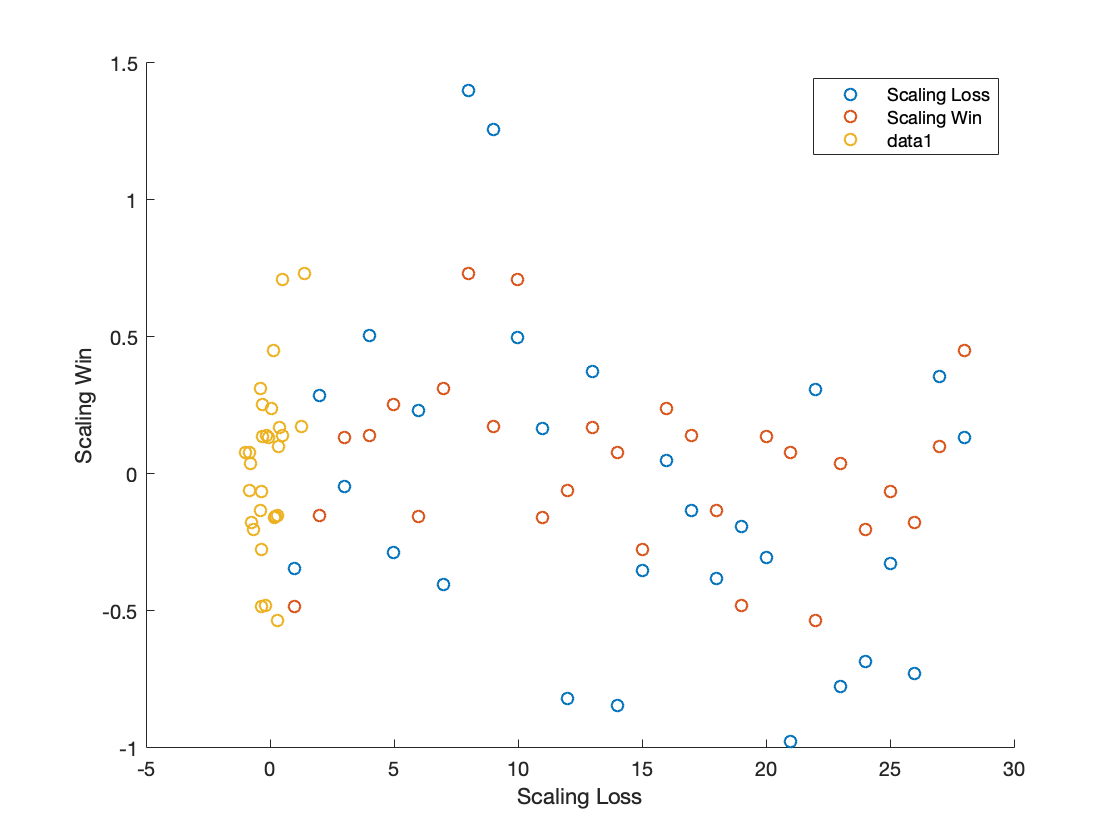


scatter(scaling_loss, scaling_win)
xlabel('Scaling Loss');
ylabel('Scaling Win');
title(fullfile(['']));

## 6. Plot model responsibility by patient group

(numbering based on the Leipzig data)

fname_hbi = load('hbi_RL_fullmodelspace.mat');
cbm = fname_hbi.cbm; 
resp = cbm.output.responsibility;

group = group'; group_idx = str2double(group);

for i = 1:nmodels
HC(i)  = [mean(resp(group_idx==0,i))];
PDI(i) = [mean(resp(group_idx==5,i))];
AUD(i) = [mean(resp(group_idx==10,i))];
Szm(i) = [mean(resp(group_idx==20,i))];
Szu(i) = [mean(resp(group_idx==21,i))];
BED(i) = [mean(resp(group_idx==30,i))];
OCD(i) = [mean(resp(group_idx==40,i))];
end

figure
for i = 1:nmodels
subplot(3,2,i)
scatter(1:40,resp(group_idx==20,i))
end



% 
% figure
% subplot(2,2,1)
% bar(HC)
% title('HC N=89')
% subplot(2,2,2)
% bar(AUD)
% title('AUD N=42')
% subplot(2,2,3)
% bar(BED)
% title('BED N=22')
% subplot(2,2,4)
% bar(OCD)
% title('OCD N=30')